## Utilizziamo anche le features

## Flag di configurazione

Variabili che permettono l'esecuzione selettiva del codice e scelta di alcuni parametri come la rete da utilizzare.

% === VARIABILI DI STAMPA ================== %
printTrainingSet = 0;
printTestSet = 0;
printConfMatr = 0;

doubleInput = 0;

## Caricamento dei dati

Vengono caricati i dati di training, validation e test set come image datastore. imageDatastore automaticamente applica le label alle classi in base ai nomi delle cartelle delle immagini e salva i dati come oggetti ImageDatastore.

% caricamento dei dati
imdsTrain = imageDatastore('dataset/TrainSet/','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('dataset/ValSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('dataset/TestSet/','IncludeSubfolders',true,'LabelSource','foldernames');
%numero di dati caricati
numTrainImages = numel(imdsTrain.Labels);
numValImages = numel(imdsValidation.Labels);
numTestImages = numel(imdsTest.Labels);

## Analisi dei dati

Stampa casuale di alcune delle immagini appartenenti al training set

if printTrainingSet == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end
end

## Preparazione dei dati

h = 128; %218;
w = 128; %178;
numChannels = 3;
numObservations = 162770;
numFeatures = 39;
numClasses = 2;
imageInputSize = [h w numChannels];

augimdsTrain = augmentedImageDatastore(imageInputSize(1:2),imdsTrain);
augimdsTest = augmentedImageDatastore(imageInputSize(1:2),imdsTest);

if doubleInput == 1
    %img
    X1Train = readall(imdsTrain);
    X1Train = cat(4,X1Train{:});

    %labels
    TTrain = imdsTrain.Labels;

    %features
    F = readmatrix('dataset/TrainSet_features.txt', 'Delimiter', ' ');
    %X2Train = F;
end

if doubleInput == 1
    dsX1Train = arrayDatastore(X1Train,IterationDimension=5);
    dsX2Train = arrayDatastore(F);
    dsTTrain = arrayDatastore(TTrain);
    dsTrain = combine(dsX1Train,dsX2Train,dsTTrain);
    %dsTrain = combine(imdsTrain,dsX2Train,dsTTrain);
end

filterSize = 40;
numFilters = 130;

if doubleInput == 0
    layers = [
        imageInputLayer(imageInputSize,Normalization="zscore")
        convolution2dLayer(filterSize,numFilters)
        batchNormalizationLayer
        reluLayer
        fullyConnectedLayer(50)
        flattenLayer
        fullyConnectedLayer(numClasses)
        softmaxLayer
        classificationLayer];
else
    layers = [
        imageInputLayer(imageInputSize,Normalization="zscore")
        convolution2dLayer(filterSize,numFilters)
        batchNormalizationLayer
        reluLayer
        fullyConnectedLayer(50)
        flattenLayer
        concatenationLayer(1,2,Name="cat")
        fullyConnectedLayer(numClasses)
        softmaxLayer
        classificationLayer];
end

lgraph = layerGraph(layers);

## Nuovo input

if doubleInput == 1
    featInput = featureInputLayer(numFeatures,Name="features");
    lgraph = addLayers(lgraph,featInput);
    lgraph = connectLayers(lgraph,"features","cat/in2");
end

## Visual network

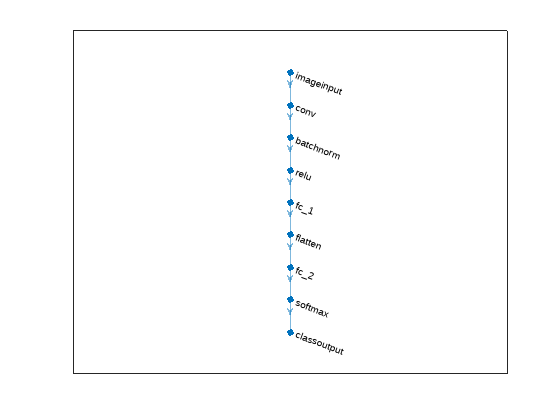

figure
plot(lgraph)

## Training Options

Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


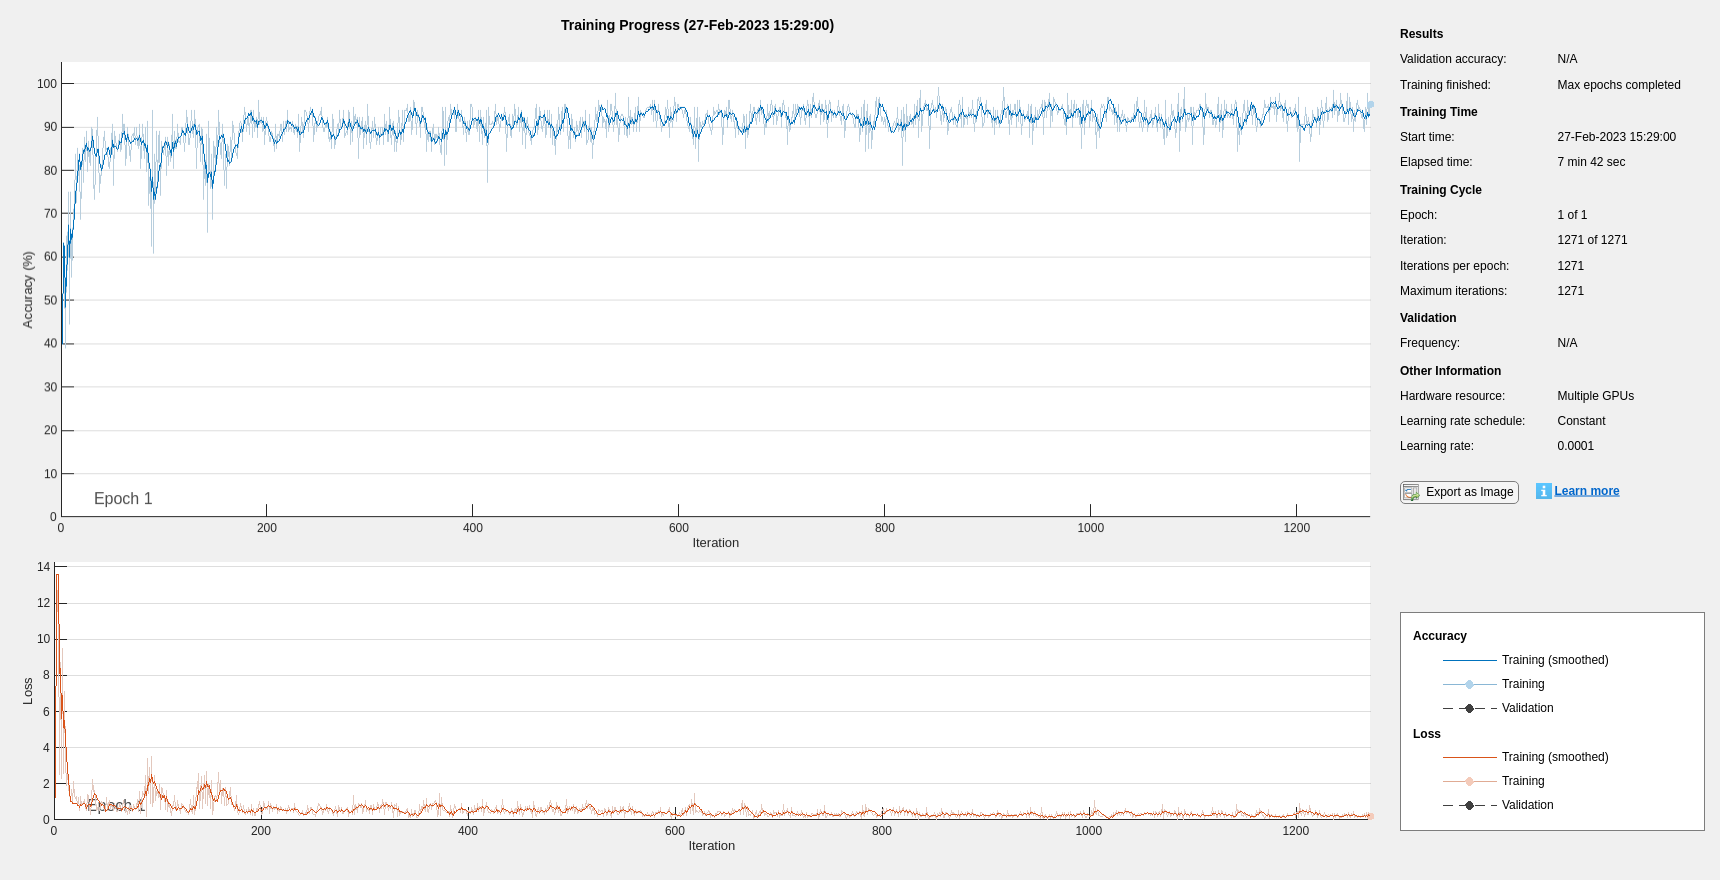

|       1 |           1 |       00:00:05 |       39.84% |       1.2495 |      1.0000e-04 |
|       1 |          50 |       00:00:23 |       90.62% |       0.4671 |      1.0000e-04 |
|       1 |         100 |       00:00:40 |       83.59% |       1.6003 |      1.0000e-04 |
|       1 |         150 |       00:00:57 |       81.25% |       1.7405 |      1.0000e-04 |
|       1 |         200 |       00:01:15 |       92.19% |       0.3054 |      1.0000e-04 |
|       1 |         250 |       00:01:33 |       92.19% |       0.3836 |      1.0000e-04 |
|       1 |         300 |       00:01:50 |       87.50% |       0.7588 |      1.0000e-04 |
|       1 |         350 |       00:02:08 |       94.53% |       0.1447 |      1.0000e-04 |
|       1 |         400 |       00:02:26 |       93.75% |       0.5155 |      1.0000e-04 |
|       1 |         450 |       00:02:44 |       92.19% |       0.3029 |      1.0000e-04 |
|       1 |         500 |       00:03:02 |       86.72% |       0.7345 |      1.0000e-04 |

tic;
options = trainingOptions("sgdm", ...
    MaxEpochs=1, ...
    InitialLearnRate=0.0001, ...
    Plots="training-progress", ...
    MiniBatchSize=128, ...
    Verbose=1, ...
    ExecutionEnvironment="multi-gpu");

if doubleInput == 1
    net = trainNetwork(dsTrain,lgraph,options);
else
    net = trainNetwork(augimdsTrain,lgraph,options);
end

## Test network

if doubleInput == 1
    dsX1Test = arrayDatastore(X1Test,IterationDimension=42);
    dsX2Test = arrayDatastore(X2Test);
    dsTest = combine(dsX1Test,dsX2Test);
    
    [YPred,scores] = classify(net,dsTest);
else
    [YPred,scores] = classify(net,augimdsTest);
end

YPred = double(YPred(:,1));
YTest = imdsTest.Labels;
YTest = double(YTest(:,1));

if printConfMatr == 1
    cm = confusionmat(YPred, YTest);
    labels = {'Female','Male'};
    figure
    plotConfMat(cm,labels)
end

time = toc;
diff = numel(find(YPred~=YTest));
[M,N] = size(YPred);
tp = M-diff;
accuracy = round(mean(YPred == YTest)*100,2);
disp('Accuracy: '+string(accuracy)+"% - Time Elapsed: "+time+" s - True Positive vs Total: "+tp+"/"+M);

Accuracy: 94.38% - Time Elapsed: 1051.8398 s - True Positive vs Total: 18841/19962
